% Last edited
Last_edited = datestr(now,1)

Last_edited = '17-Jun-2023'

clear Last_edited

## Load the data and write them to a table

clear; close all; clc;
addpath __self_func__/
addpath subinfo/

subids = [0,1:5,10:12,15:17];
subnames = {'CHAN PUI LING','lx','SLJ','李卓然','cmj','hyf','cyl','sjj','hhl','xkd','wyb','SJQ'};

subgender = zeros(1,length(subnames))';
subage = zeros(1,length(subgender))';

for id = [1:length(subids)]
    load([num2str(subids(id)),'_',subnames{id},'.mat'])
    subgender(id) = SubGender;
    subage(id) = SubAge;
end


girlnum = length(find(subgender == 2))

girlnum = 5

girlnum / length(subage)

ans = 0.4167

std(subage)

ans = 1.4975

## Draw PsychMetric Curves

In this section, we reprocess all the data and draw the psychmetric curves accordingly.

First, we clean the data and rid of all the extreme RT trials.

Then, we computed each individual parameters and save them in the form of table for later analysis.

Besides, we save all the parameters after model fitting for furthur analysis.

### Output

- Summary table for each participant

- Individual PsychMetric Curve for each participant

- Collective stats table record all participants' data

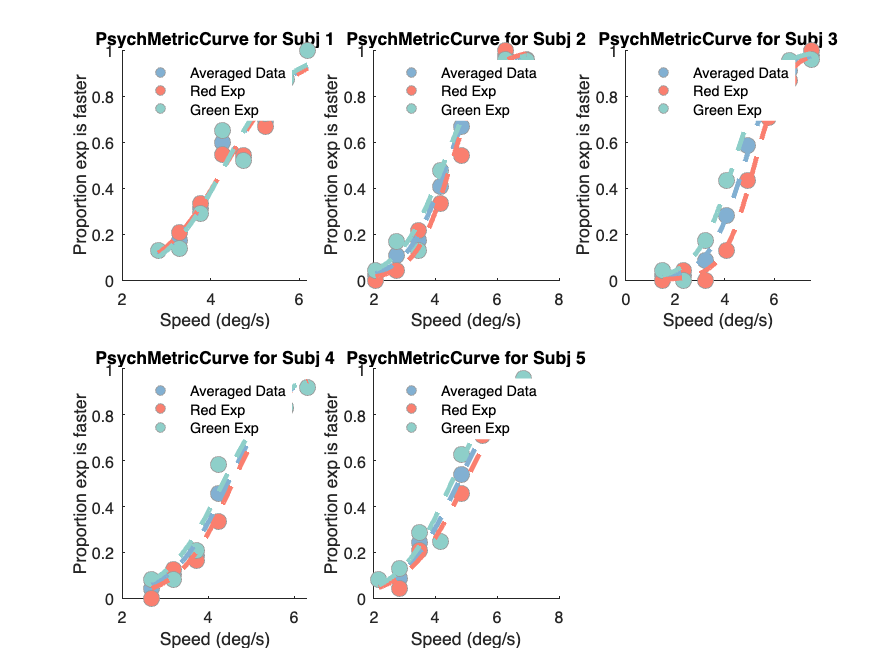

Subj_1_speed_choose = 8×2 table
    all_exp_levels             choose_exp          
    ______________    _____________________________

        2.8071        0.13043    0.13043    0.13043
           3.3        0.17391    0.20833    0.13636
        3.7714         0.3125    0.33333    0.29167
        4.2643            0.6    0.54545    0.65217
        4.7357        0.53191    0.54167    0.52174
        5.2286        0.69565    0.66667    0.72727
           5.7          0.875      0.875      0.875
        6.1929              1          1          1


Subj_2_speed_choose = 8×2 table
    all_exp_levels               choose_exp           
    ______________    ________________________________

        2.0571        0.020833           0    0.041667
        2.7429         0.10638    0.043478     0.16667
          3.45         0.17391     0.21739     0.13043
        4.1571         0.40909     0.33333     0.47826
        4.8429         0.66667     0.54167     0.79167
          5.55         0.86957     0.91304     0.82609
        6.2571         0.97872           1     0.95833
        6.9429         0.95745     0.95833     0.95652


Subj_3_speed_choose = 8×2 table
    all_exp_levels               choose_exp           
    ______________    ________________________________

           1.5        0.020833           0    0.041667
        2.3571        0.021277    0.041667           0
        3.2143        0.086957           0     0.17391
        4.0714         0.28261     0.13043     0.43478
        4.9286         0.58696     0.43478     0.73913
        5.7857         0.78723     0.70833     0.86957
        6.6429         0.91304     0.86957     0.95652
           7.5         0.97872           1     0.95833


Subj_4_speed_choose = 8×2 table
    all_exp_levels               choose_exp           
    ______________    ________________________________

        2.6786        0.041667           0    0.083333
        3.1929         0.10417       0.125    0.083333
        3.7286          0.1875     0.16667     0.20833
        4.2429         0.45833     0.33333     0.58333
        4.7571         0.74468     0.73913        0.75
        5.2714         0.80851     0.78261     0.83333
        5.8071         0.82979     0.82609     0.83333
        6.3214         0.91667     0.91667     0.91667


Subj_5_speed_choose = 8×2 table
    all_exp_levels               choose_exp           
    ______________    ________________________________

        2.1643        0.083333    0.083333    0.083333
        2.8286        0.085106    0.041667     0.13043
        3.4929         0.24444     0.20833     0.28571
        4.1571            0.25        0.25        0.25
        4.8429         0.54167     0.45833       0.625
        5.5071         0.72917     0.70833        0.75
        6.1714         0.85106     0.79167     0.91304
        6.8357         0.91667       0.875     0.95833


figure;
PSEs = zeros(length(subids),3);
JNDs = zeros(length(subids),3);
d_primes = zeros(length(subids),3);
criterions = zeros(length(subids),3);

for id = [1:length(subids)]
    load(['Results_',num2str(id),'_',subnames{id},'.mat'])
    %%%%%%%% Processing the data
    % This part is not necessary with given data
    % our original data was too big in filesize；
    % so we rearranged our data

    %     velocity = zeros(length(trajectories),2);
    %     for ti = [1:length(trajectories)]
    %         currenttrial = trajectories{ti,1};
    %         velocity(ti,:) = currenttrial.velocity;
    %     end
    %     Vs = round(velocity,2);
    %     V_con = Vs(:,1); V_exp = Vs(:,2);
    %     result_name = ['Results_',num2str(id),'_',subnames{id},'.mat'];
    %     save(result_name,"V_exp","V_con","exp_cond","res","correct_ans","yesno","RTs")
    res = res'; correct_ans = correct_ans'; yesno = yesno'; RTs = RTs';

    % convert data from pix/frame to deg/s
    V_exp = V_exp / (mean(V_con) / 4.5);
    Summary_table = table(V_con,V_exp,exp_cond,res,correct_ans,yesno,RTs);

    % Clean data; rid of extreme RTs
    idx  = find(abs(Summary_table.RTs - mean(Summary_table.RTs))...
        < 3*std(Summary_table.RTs));
    Summary_table = Summary_table(idx,:);
    Summary_table = renamevars(Summary_table,["res","correct_ans","yesno","RTs"],...
        ["res","exphigher","accuracy","RT"]);
    mean_acc = groupsummary(Summary_table,"V_exp",'mean').mean_accuracy;
    all_exp_levels = groupsummary(Summary_table,"V_exp").V_exp;
    Summary_con1 = Summary_table(Summary_table.exp_cond == 1,:);
    acc_con1 = groupsummary(Summary_con1,"V_exp",'mean').mean_accuracy;
    Summary_con2 = Summary_table(Summary_table.exp_cond == 2,:);
    acc_con2 = groupsummary(Summary_con2,"V_exp",'mean').mean_accuracy;
    accs = 1 - [mean_acc, acc_con1, acc_con2];
    if id == 3
        accs = 1-accs;
    end
    choose_exp = zeros(length(all_exp_levels),3);
    choose_exp([1:4],:) = 1 - accs([1:4],:);
    choose_exp(5:end,:) = accs(5:end,:);
    eval(sprintf('Subj_%d_speed_choose = table(all_exp_levels,choose_exp)',id));

    %%%%%%%% Calculate the dprime and criterion
    [dprime_all,c_all] = dprime(mean(choose_exp([5:8],1)),mean(choose_exp([1:4],1)));
    [dprime_red,c_red] = dprime(mean(choose_exp([5:8],2)),mean(choose_exp([1:4],2)));
    [dprime_green,c_green] = dprime(mean(choose_exp([5:8],3)),mean(choose_exp([1:4],3)));

    %%%%%%%% Fit the curves and draw
    subplot(2,3,id);
    % Plot the made up data
    s1 = scatter(all_exp_levels,choose_exp(:,1),100,"MarkerEdgeColor","#999999",...
        "MarkerFaceColor","#82B0D2");
    hold on
    s2 = scatter(all_exp_levels,choose_exp(:,2),100,"MarkerEdgeColor","#999999",...
        "MarkerFaceColor","#FA7F6F");
    hold on
    s3 = scatter(all_exp_levels,choose_exp(:,3),100,"MarkerEdgeColor","#999999",...
        "MarkerFaceColor","#8ECFC9");
    ylabel('Proportion exp is faster')
    xlabel('Speed (deg/s)')
    % Fit to the Psychometric curve
    targets = [0.25, 0.5, 0.75]; % 25%, 50% and 75% performance
    weights = ones(1,length(all_exp_levels)); % No weighting
    % Fit for all conditions
    [coeffs_all, stats_all, curve_all, threshold_all] = ...
        FitPsychCurveLogit(all_exp_levels, choose_exp(:,1), weights, targets);
    [coeffs_red, stats_red, curve_red, threshold_red] = ...
        FitPsychCurveLogit(all_exp_levels, choose_exp(:,2), weights, targets);
    [coeffs_green, stats_green, curve_green, threshold_green] = ...
        FitPsychCurveLogit(all_exp_levels, choose_exp(:,3), weights, targets);
    plot(curve_all(:,1), curve_all(:,2), 'LineStyle', '--','Color',"#82B0D2",...
        "LineWidth",3);
    hold on
    plot(curve_red(:,1), curve_red(:,2), 'LineStyle', '--','Color',"#FA7F6F",...
        "LineWidth",3);
    hold on
    plot(curve_green(:,1), curve_green(:,2), 'LineStyle', '--','Color',"#8ECFC9",...
        "LineWidth",3);
    legend([s1,s2,s3],["Averaged Data","Red Exp","Green Exp"],...
        'Location','northwest',"Box","off");
    title(['PsychMetricCurve for Subj ',num2str(id)],'FontWeight','bold')
    f1 = gcf;

    %%%%%%%% save the individual params
    PSE_all = threshold_all(2);
    PSE_red = threshold_red(2);
    PSE_green = threshold_green(2);
    JND_all = (threshold_all(3) - threshold_all(1))/2;
    JND_red = (threshold_red(3) - threshold_red(1))/2;
    JND_green = (threshold_green(3) - threshold_green(1))/2;
    PSEs(id,:) = [PSE_all, PSE_red, PSE_green];
    JNDs(id,:) = [JND_all, JND_red, JND_green];
    d_primes(id,:) = [dprime_all,dprime_red,dprime_green];
    criterions(id,:) = [c_all, c_red, c_green];
end


RowNames_stats = {};
for si = 1:length(subids);RowNames_stats{si} = ['Subj_',num2str(si)];end
stats_table = table(PSEs,JNDs,d_primes,criterions,...
    'RowNames',RowNames_stats)

stats_table = 5×4 table
                         PSEs                           JNDs                          d_primes                          criterions              
              __________________________    _____________________________    __________________________    _____________________________________

    Subj_1    4.3234    4.3308     4.318    0.79165    0.82658    0.75463    1.2699    1.2534    1.2924     -0.12262      -0.11489      -0.12941
    Subj_2    4.3688    4.4949    4.2455    0.71785    0.63533    0.78728    2.0422    2.0932    2.0174    -0.096367    -0.0039262      -0.18219
    Subj_3    4.7813    5.2055    4.3481    0.80385    0.68971    0.81355    2.1672    2.4011    2.1633      0.18151       0.51605     -0.097785
    Subj_4    4.4488    4.5612    4.3348    0.

## Basic Testing

Here, we test if the resulted PSE is really significantly different from the control speed.

Also, we'll see the differences between each conditions.

%%%%%% Testing if PSE different from 2.1
PSE_stats = zeros(3,2); PSE_bootstrap = zeros(3,2);
PSE_all = PSEs(:,1);
[h,p,ci,stats] = ttest(PSE_all,2.1,"Alpha",0.05);
PSE_stats(1,1) = mean(PSE_all); PSE_stats(1,2) = p;
PSE_red = PSEs(:,2);
[h,p,ci,stats] = ttest(PSE_red,2.1,"Alpha",0.05);
PSE_stats(2,1) = mean(PSE_red); PSE_stats(2,2) = p;
PSE_green = PSEs(:,3);
[h,p,ci,stats] = ttest(PSE_green,2.1,"Alpha",0.05);
PSE_stats(3,1) = mean(PSE_green); PSE_stats(3,2) = p;

% After Bootstrapping, all significant
[bootstats, bootsam] = bootstrp(500,@mean,PSE_all);
[h,p,ci,stats] = ttest(bootstats,2.1,"Alpha",0.05);
PSE_bootstrap(1,:) = [mean(bootstats),p];
[bootstats, bootsam] = bootstrp(500,@mean,PSE_red);
[h,p,ci,stats] = ttest(bootstats,2.1,"Alpha",0.05);
PSE_bootstrap(2,:) = [mean(bootstats),p];
[bootstats, bootsam] = bootstrp(500,@mean,PSE_green);
[h,p,ci,stats] = ttest(bootstats,2.1,"Alpha",0.05);
PSE_bootstrap(3,:) = [mean(bootstats),p];

% Write this results to a table
PSE_table = table(PSE_stats,PSE_bootstrap, 'RowNames',{'all';'red';'green'})

PSE_table = 3×2 table
                  PSE_stats           PSE_bootstrap  
             ____________________    ________________

    all      4.5285    1.3009e-05    4.5362         0
    red      4.7057    8.2147e-05    4.7011         0
    green    4.3499    7.3948e-07    4.3473         0


Then, will see the difference between different conditions;

Here we only compare the difference between when experiment dot is red or green;

but in the following studies we'll also test if interference has any impact on the results;

%%%%%% Testing if PSE, JND, d-prime, criterion if different for green and
%%%%%% red conditions
vars = {'PSE','JND','d_prime','criterion'};
cons = {'red', 'green'};
bootnum = 50;
for v = [1:length(vars)]
    for c = [1:length(cons)]
        eval(sprintf('%s_%s=%ss(:,%d);',vars{v},cons{c},vars{v},c+1));
    end
    temp_red = eval(sprintf('%s_red;',vars{v}));
    temp_green = eval(sprintf('%s_green;',vars{v}));
    [h,p,ci,stats] = ttest(temp_red,temp_green,'Alpha',0.05);
    se = [std(temp_red)/sqrt(length(subids)),std(temp_green)/sqrt(length(subids))];
    eval(sprintf('%s_Stats = [mean(%s_red);mean(%s_green);stats.tstat;p];',vars{v},vars{v},vars{v}));

    % after bootstrapping
    [bootstats,bootsam] = bootstrp(500,@mean,[temp_red,temp_green]);
    [h,p,ci,stats] = ttest(bootstats(:,1),bootstats(:,2),"Alpha",0.05);
    temp_cm = sprintf('%s_Bootstats = [mean(bootstats(:,1));mean(bootstats(:,2));stats.tstat;p];',vars{v});
    se_b = [std(bootstats(:,1))/sqrt(50),std(bootstats(:,2))/sqrt(50)];
    eval(temp_cm)
end

compare_table = table(PSE_Stats,PSE_Bootstats,JND_Stats,JND_Bootstats,...
    d_prime_Stats,d_prime_Bootstats,criterion_Stats,criterion_Bootstats,...
    'RowNames',{'M(red)';'M(green)';'t-value';'p'})

compare_table = 4×8 table
                PSE_Stats    PSE_Bootstats    JND_Stats    JND_Bootstats    d_prime_Stats    d_prime_Bootstats    criterion_Stats    criterion_Bootstats
                _________    _____________    _________    _____________    _____________    _________________    _______________    ___________________

    M(red)        4.7057           4.7073      0.76598         0.75971          1.8523              1.8442            0.14097                0.13719    
    M(green)      4.3499           4.3515      0.80098         0.79856          1.7839              1.7776           -0.10747               -0.10738    
    t-value       2.5055           63.

## Draw Bar Plot

Now we have some basic stats and decriptive data, we can visualize the results we get.

Plus, because we aim to explore more in our formal experiment (now it is just a pilot and our results parly confirm our hypothesis),

we additionally pre-code how we are going to conduct analysis with later data,

% Draw Bar Plot for current data

- red indicates significant results;

- green means marginally significant;

- blue indicates no significant difference;

Yet we don't have enough

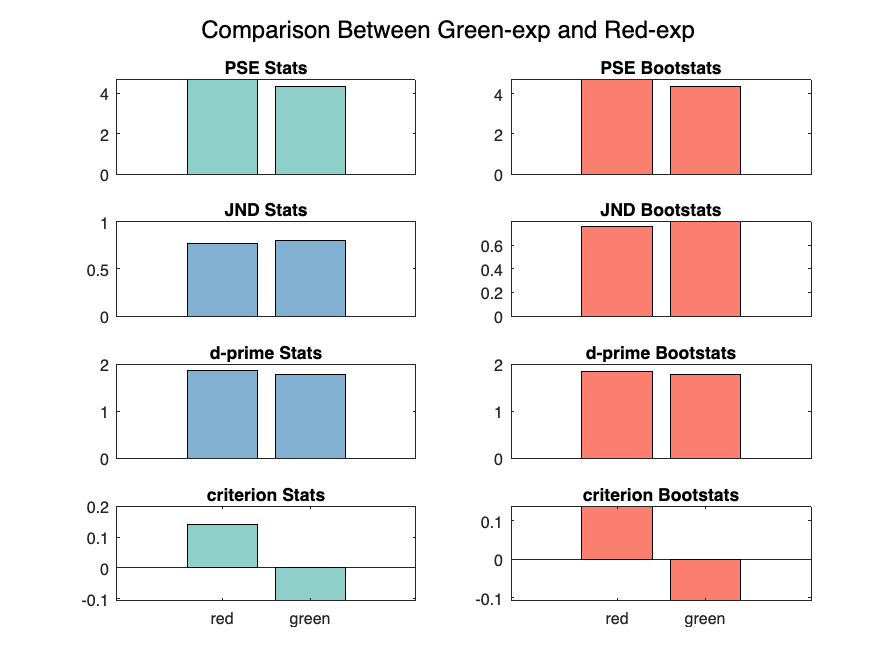

vars = {'PSE','JND','d_prime','criterion'};
vars_rn = {'PSE','JND','d-prime','criterion'};
statis = {'Stats','Bootstats'};

figure;
pi = 1;
for vi = 1:length(vars)
    for si = 1:length(statis)
        subplot(4,2,pi); pi = pi +1;
        current_dt = eval(sprintf('compare_table.%s_%s',vars{vi},statis{si}));
        if current_dt(4) < 0.05
            draw_color = "#FA7F6F";
        elseif (current_dt(4) >= 0.05) && (current_dt(4) < 0.1)
            draw_color = "#8ECFC9";
        else
            draw_color = "#82B0D2";
        end
        bar(current_dt(1:2),'FaceColor',draw_color)
        title(sprintf('%s %s',vars_rn{vi},statis{si}))
        if vi == length(vars)
            set(gca,'XTickLabel',{'red','green'});
        else
            xticks('')
        end
    end
end

sgtitle('Comparison Between Green-exp and Red-exp');

f2 = gcf;

## Write to excel

Last, we write the statistics and data we've acquired to a table and save the image.

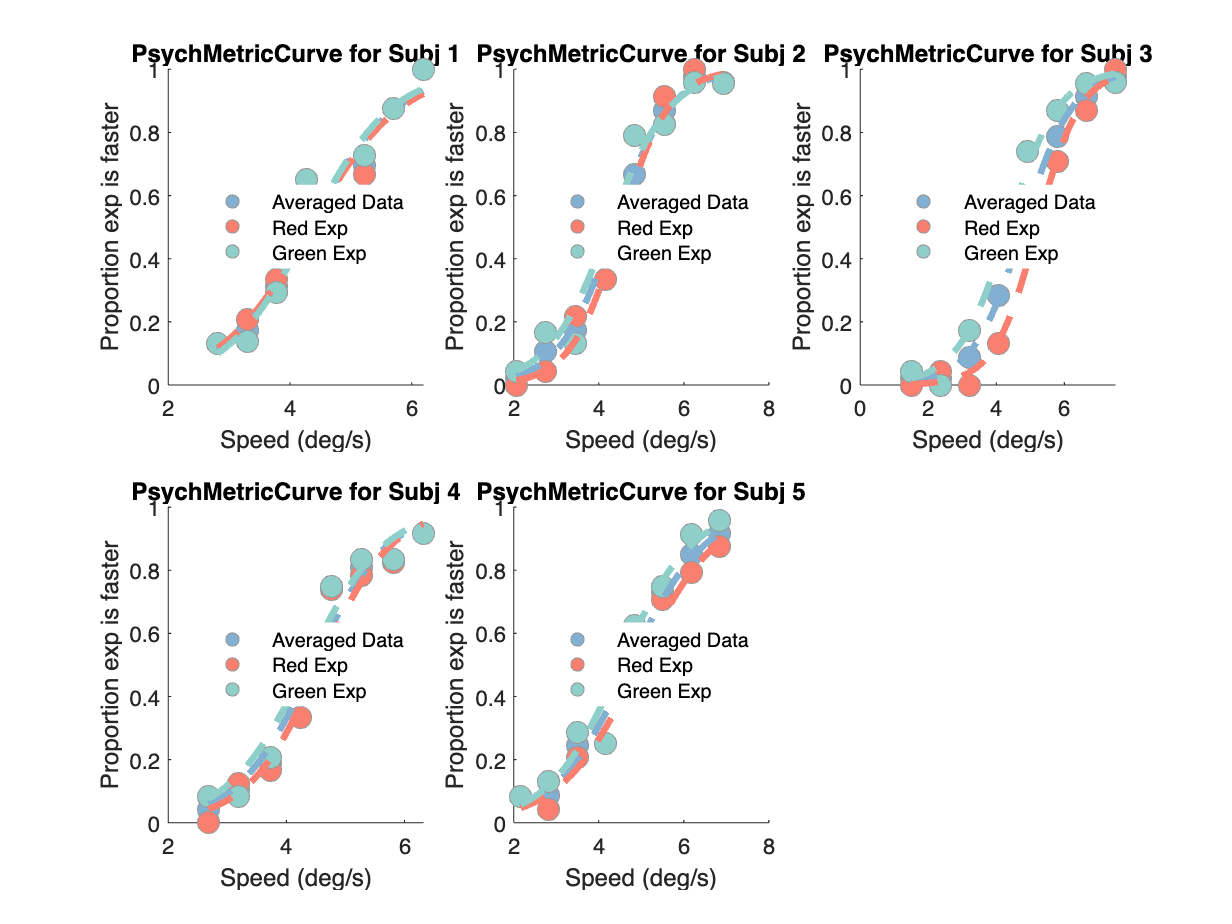

if ~ exist('tables/')
    mkdir tables/
    mkdir tables/plots/
end

% save the psychmetric curve
filename = 'CurveFitting';
saveas(f1,['tables/plots/',filename,'.fig']);
saveas(f1,['tables/plots/',filename,'.png']);

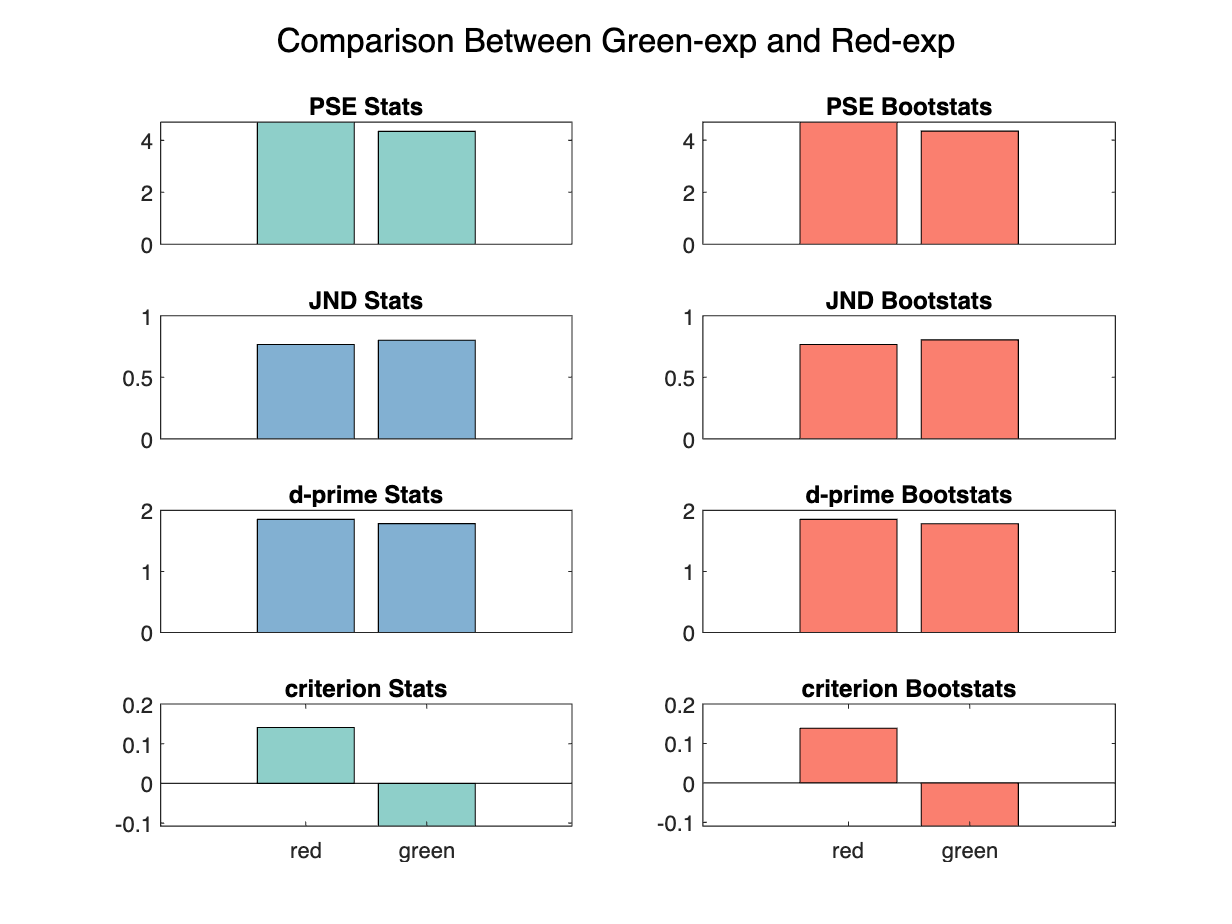


filename = 'barresults';
saveas(f2,['tables/plots/',filename,'.fig']);
saveas(f2,['tables/plots/',filename,'.png']);


% save the indiviudal data and testing results

filename = sprintf('tables/Individual_choose.xlsx');
for si = [1:length(subids)]
    curr_t = eval(sprintf('Subj_%d_speed_choose;',si));
    writetable(curr_t,filename,'Sheet',si,'Range','A1');
end

filename = sprintf('tables/group_stats.xlsx');
writetable(stats_table,filename,'Sheet',1,'Range','A1');
writetable(PSE_table,filename,'Sheet',2,'Range','A1');
writetable(compare_table,filename,'Sheet',3,'Range','A1');

## Later Comparison Demo

Because we firstly conducted pilot studies to test if our experiment is meaningful, we made adjustments to our current code and generate different data type;

We show here how we plan to analyze our future data in formal experiment:

Now assume that we have the kind of data we want:

- It will has 2 (audiovisual / no audio ) x 2 (red / green) x 2 (interference / no inte) conditions;

- we can draw psychmetric curves with each factors and then compare the PSE, JND, d-prime and criterion of each condition;

I will demonstrate this analysis with my own data and resampled results:

Because other analyses are similar to before, here only show use anova compare:

clc; clear; close all;

load Results_mine.mat

res = res'; correct_ans = correct_ans'; RTs = RTs';

% convert data from pix/frame to deg/s
V_exp = V_exp / (mean(V_con) / 4.5);
Summary_table = table(V_con,V_exp,exp_cond,aud_cond,inf_cond,res,correct_ans,yesno,RTs);
pool_table = Summary_table(find(Summary_table.RTs ~= 0),:);

nsi = 10;

PSEs = zeros(nsi,8); % audio / color / interference
JNDs = zeros(nsi,8);
d_primes = zeros(nsi,8);
criterions = zeros(nsi,8);

for si = 1:nsi
    % generate data
    idx = randi(192, 1,200);
    Summary_table = pool_table([1:length(pool_table.RTs),idx],:);
    % Clean data; rid of extreme RTs
    idx  = find(abs(Summary_table.RTs - mean(Summary_table.RTs))...
        < 3*std(Summary_table.RTs));
    Summary_table = Summary_table(idx,:);
    Summary_table = renamevars(Summary_table,["res","correct_ans","yesno","RTs"],...
        ["res","exphigher","accuracy","RT"]);

    fillin = 1;
    for xi = 1:2
        for yi = 1:2
            for zi = 1:2
                mean_acc = groupsummary(Summary_table,"V_exp",'mean').mean_accuracy;
                all_exp_levels = groupsummary(Summary_table,"V_exp").V_exp;
                Summary_con1 = Summary_table(...
                    (Summary_table.exp_cond == xi) & (Summary_table.inf_cond == yi)...
                    & (Summary_table.aud_cond == zi),:);
                acc = groupsummary(Summary_con1,"V_exp",'mean').mean_accuracy;
                choose_exp = zeros(length(all_exp_levels),1);
                choose_exp([1:4],:) = 1 - acc([1:4],:);
                choose_exp(5:end,:) = acc(5:end,:);
                % Calculate the dprime and criterion
                [dprime_temp,c_temp] = dprime(mean(choose_exp([5:8],1)),mean(choose_exp([1:4],1)));
                d_primes(si,fillin) = dprime_temp;
                criterions(si,fillin) = c_temp;
                fillin = fillin + 1;
            end
        end
    end
end


%%% compare d_primes

d_primes_anova = d_primes(:)

d_primes_anova =     2.6813
    3.0132
    3.0736
    2.8482
    2.7071
    3.1790
    2.7436
    2.3504
    2.4319
    2.8157


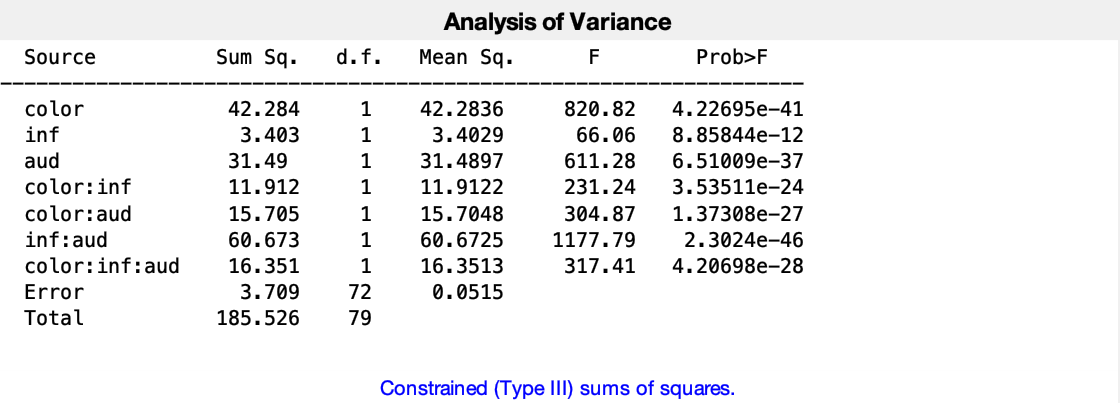

p = 1.0e-11 *

    0.0000
    0.8858
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


table = 10×7 cell array
    {'Source'       }    {'Sum Sq.' }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'         }    {'Prob>F'    }
    {'color'        }    {[ 42.2836]}    {[   1]}    {[        0]}    {[ 42.2836]}    {[  820.8173]}    {[4.2269e-41]}
    {'inf'          }    {[  3.4029]}    {[   1]}    {[        0]}    {[  3.4029]}    {[   66.0584]}    {[8.8584e-12]}
    {'aud'          }    {[ 31.4897]}    {[   1]}    {[        0]}    {[ 31.4897]}    {[  611.2838]}    {[6.5101e-37]}
    {'color:inf'    }    {[ 11.9122]}    {[   1]}    {[        0]}    {[ 11.9122]}    {[  231.2414]}    {[3.5351e-24]}
    {'color:aud'    }    {[ 15.7048]}    {[   1]}    {[        0]}    {[ 15.7048]}    {[  304.8653]}    {[1.3731e-27]}
    {'inf:aud'      }    {[ 60.6725]}    {[   1]}    {[        0]}    {[ 60.6725]}    {[1.1778e+03]}    {[2.3024e-46]}
    {'color:inf:aud'}    {[ 16.3513]}    {[   1]}    {[        0]}    {[ 16.3513]}    {[  317.4145]}    {[4.2070e-28]}
    {'Error'        }   

stats = struct with fields:
         source: 'anovan'
          resid: [80×1 double]
         coeffs: [27×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×27 double]
            dfe: 72
            mse: 0.0515
    nullproject: [27×8 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {27×1 cell}
           vars: [27×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [8×8 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


term =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1
     1     1     1


color = strcat({'Col'},num2str([ones(40,1);2*ones(40,1)]));
inf =strcat({'Inf'},num2str([ones(20,1);2*ones(20,1)]));
inf =[inf;inf];
aud = strcat({'Aud'},num2str([ones(10,1);2*ones(10,1)]));
aud = [aud;aud;aud;aud];

varnames={'color','inf','aud'};

[p,table,stats,term]=anovan(d_primes_anova,...
    {color,inf,aud},'model','full','varnames',varnames)

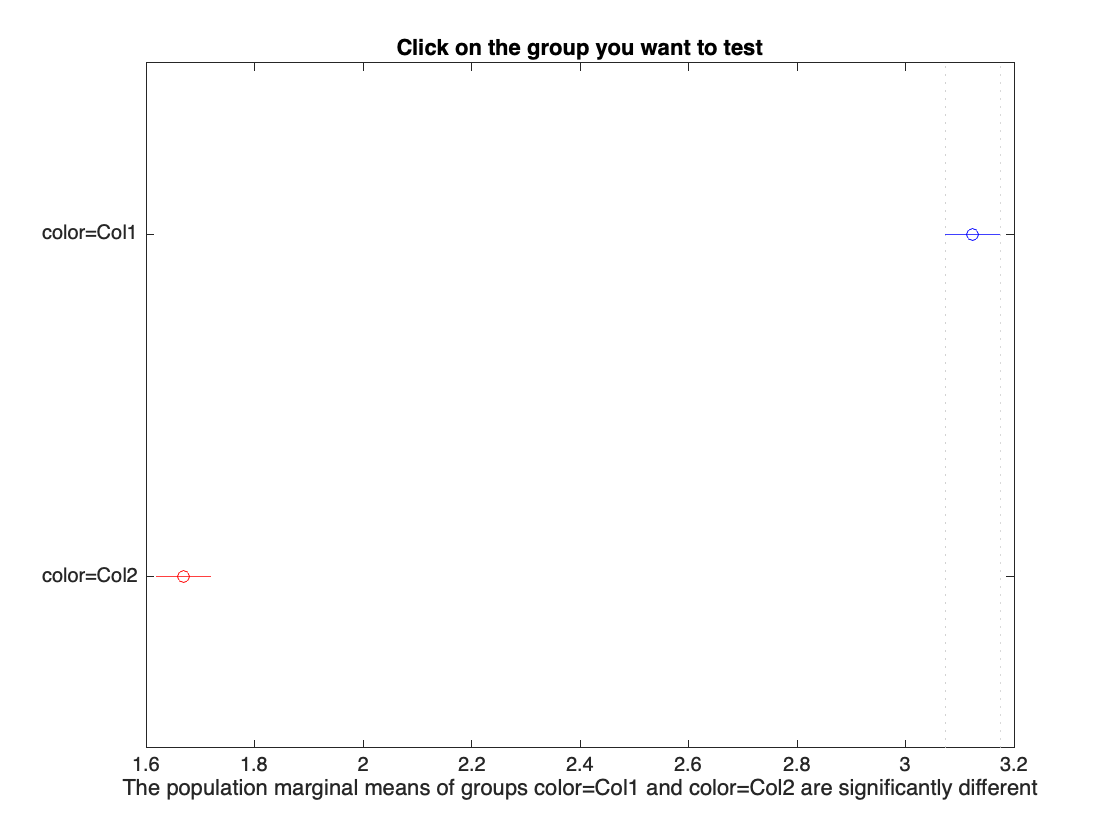

c =     1.0000    2.0000    1.3529    1.4540    1.5552         0


m =     3.1240    0.0359
    1.6700    0.0359


h =   Figure (13: Multiple comparison of population marginal means) with properties:

      Number: 13
        Name: 'Multiple comparison of population marginal means'
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


gnames = 2×1 cell array
    {'color=Col1'}
    {'color=Col2'}


[c,m,h,gnames]=multcompare(stats)



%%% compare criterions

criterions_anova = criterions(:)

criterions_anova =     0.3042
    0.2251
    0.1538
    0.0411
    0.1117
   -0.0554
    0.2214
    0.2078
    0.0656
    0.1263


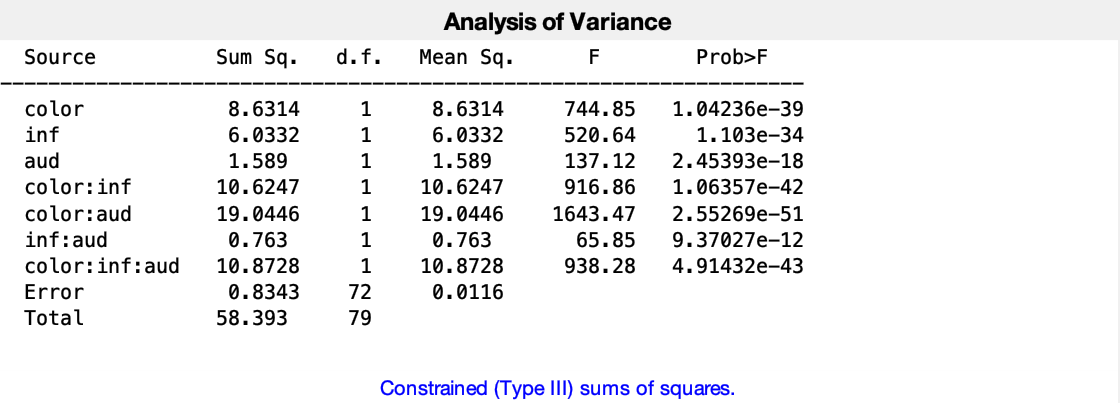

p = 1.0e-11 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.9370
    0.0000


table = 10×7 cell array
    {'Source'       }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'         }    {'Prob>F'    }
    {'color'        }    {[ 8.6314]}    {[   1]}    {[        0]}    {[  8.6314]}    {[  744.8535]}    {[1.0424e-39]}
    {'inf'          }    {[ 6.0332]}    {[   1]}    {[        0]}    {[  6.0332]}    {[  520.6402]}    {[1.1030e-34]}
    {'aud'          }    {[ 1.5890]}    {[   1]}    {[        0]}    {[  1.5890]}    {[  137.1233]}    {[2.4539e-18]}
    {'color:inf'    }    {[10.6247]}    {[   1]}    {[        0]}    {[ 10.6247]}    {[  916.8647]}    {[1.0636e-42]}
    {'color:aud'    }    {[19.0446]}    {[   1]}    {[        0]}    {[ 19.0446]}    {[1.6435e+03]}    {[2.5527e-51]}
    {'inf:aud'      }    {[ 0.7630]}    {[   1]}    {[        0]}    {[  0.7630]}    {[   65.8462]}    {[9.3703e-12]}
    {'color:inf:aud'}    {[10.8728]}    {[   1]}    {[        0]}    {[ 10.8728]}    {[  938.2783]}    {[4.9143e-43]}
    {'Error'        }    {[ 0.83

stats = struct with fields:
         source: 'anovan'
          resid: [80×1 double]
         coeffs: [27×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×27 double]
            dfe: 72
            mse: 0.0116
    nullproject: [27×8 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {27×1 cell}
           vars: [27×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [8×8 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


term =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1
     1     1     1


color = strcat({'Col'},num2str([ones(40,1);2*ones(40,1)]));
inf =strcat({'Inf'},num2str([ones(20,1);2*ones(20,1)]));
inf =[inf;inf];
aud = strcat({'Aud'},num2str([ones(10,1);2*ones(10,1)]));
aud = [aud;aud;aud;aud];

varnames={'color','inf','aud'};

[p,table,stats,term]=anovan(criterions_anova,...
    {color,inf,aud},'model','full','varnames',varnames)

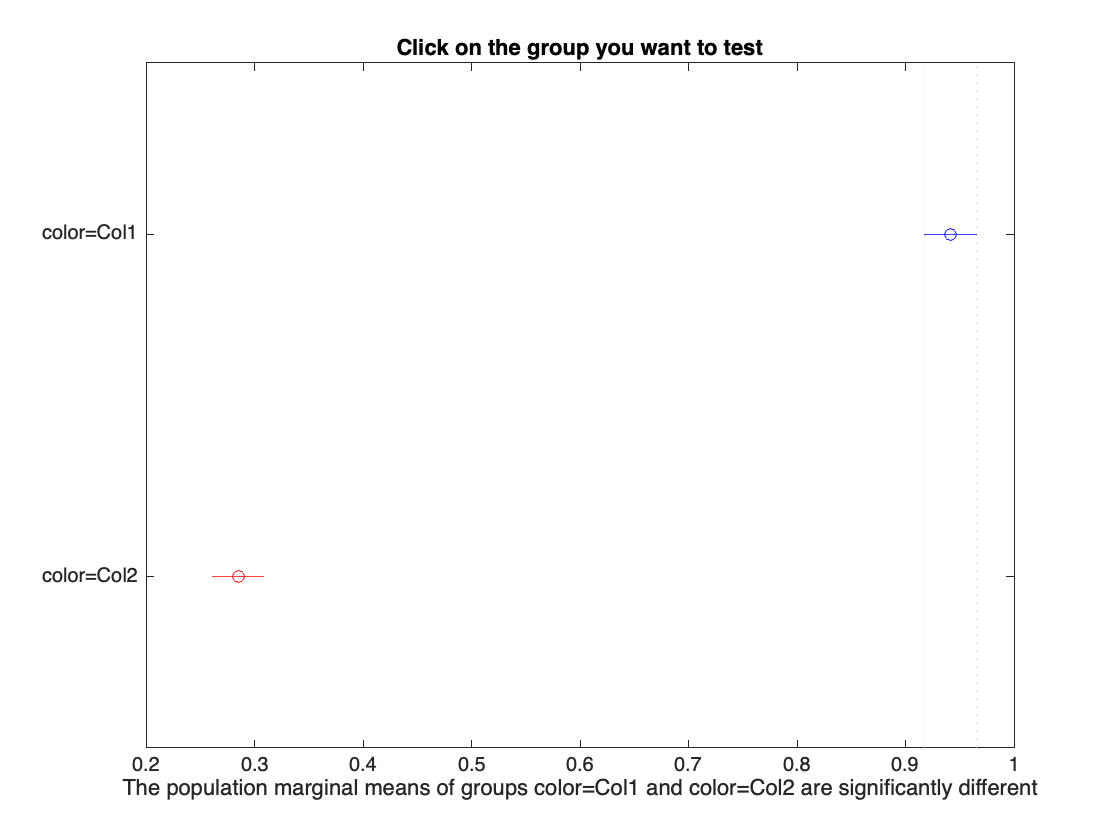

c =     1.0000    2.0000    0.6090    0.6569    0.7049         0


m =     0.9417    0.0170
    0.2848    0.0170


h =   Figure (13: Multiple comparison of population marginal means) with properties:

      Number: 13
        Name: 'Multiple comparison of population marginal means'
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


gnames = 2×1 cell array
    {'color=Col1'}
    {'color=Col2'}


[c,m,h,gnames]=multcompare(stats)